clear; clc;
load('toy.mat')

Xtr = toy(:, 1:2);
Ytr = dummyvar(categorical(toy(:, 3))); % OHE

**Classical kernel PCA under RKM framework**

s =200;
params = {'rbf_func', 0.5, 'eta1', 1, 'eta2', 1, 'gamma', 0.001};
[V, D, K] = multiview_skpca_rkm(Xtr, Ytr, [], [], params, s, 1, 0); % classical kPCA

**Plot**

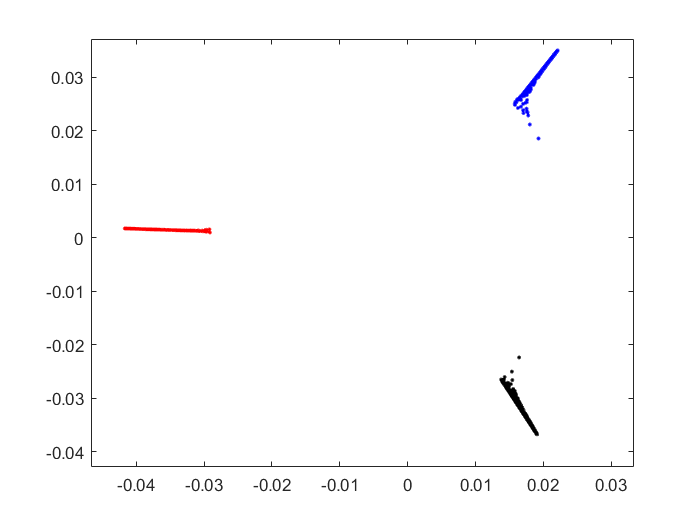

% Graph: 1-2nd PC
plot(V(toy(:, 3) == 1, 1), V(toy(:, 3) == 1, 2), 'b.', ...
    V(toy(:, 3) == 2, 1), V(toy(:, 3) == 2, 2), 'k.', ...
    V(toy(:, 3) == 3, 1), V(toy(:, 3) == 3, 2), 'r.')

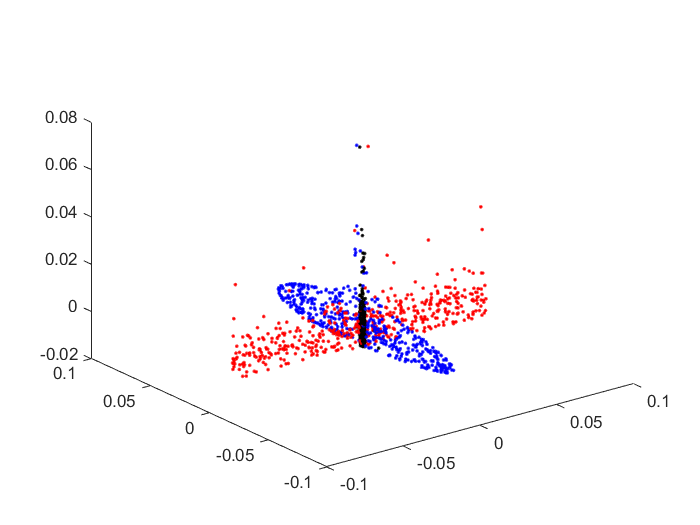


% Graph: 3-5th PC
plot3(V(toy(:, 3) == 1, 3), V(toy(:, 3) == 1, 4), V(toy(:, 3) == 1, 5), 'b.', ...
    V(toy(:, 3) == 2, 3), V(toy(:, 3) == 2, 4), V(toy(:, 3) == 1, 5), 'k.', ...
    V(toy(:, 3) == 3, 3), V(toy(:, 3) == 3, 4), V(toy(:, 3) == 1, 5), 'r.')

**Sparse kernel PCA under RKM framework**

s =200;
params = {'rbf_func', 0.5, 'eta1', 1, 'eta2', 1, 'gamma', 0.003};
[Vs, Ds, Ks] = multiview_skpca_rkm(Xtr, Ytr, [], [], params, s, 0, 0); % sparse kPCA

**Plot**

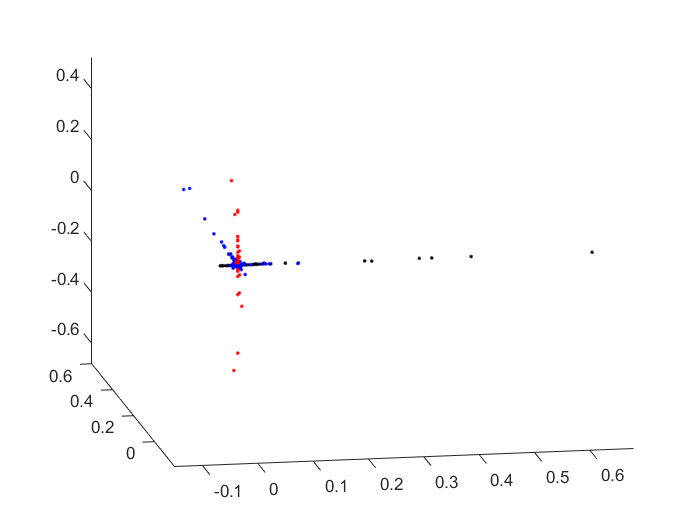

% Graph: 1-3rd PC
plot3(Vs(toy(:, 3) == 1, 1), Vs(toy(:, 3) == 1, 2), Vs(toy(:, 3) == 1, 3), 'b.', ...
    Vs(toy(:, 3) == 2, 1), Vs(toy(:, 3) == 2, 2), Vs(toy(:, 3) == 2, 3), 'k.', ...
    Vs(toy(:, 3) == 3, 1), Vs(toy(:, 3) == 3, 2), Vs(toy(:, 3) == 3, 3), 'r.')

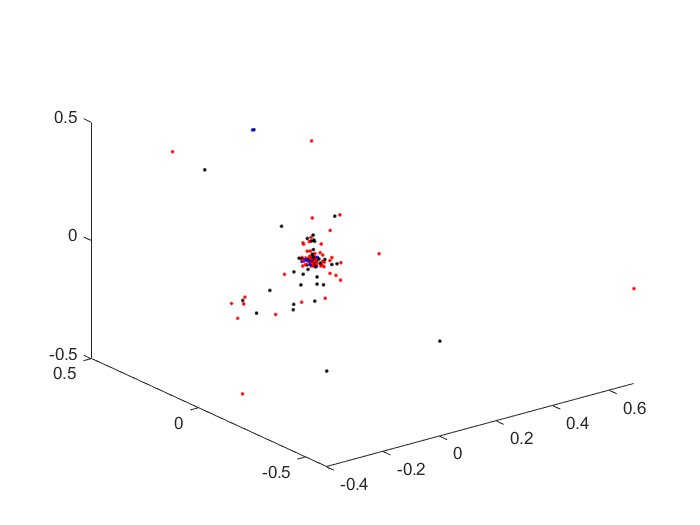


% Graph: 4-6th PC
plot3(Vs(toy(:, 3) == 1, 4), Vs(toy(:, 3) == 1, 5), Vs(toy(:, 3) == 1, 6), 'b.', ...
    Vs(toy(:, 3) == 2, 4), Vs(toy(:, 3) == 1, 5), Vs(toy(:, 3) == 1, 6), 'k.', ...
    Vs(toy(:, 3) == 3, 4), Vs(toy(:, 3) == 1, 5), Vs(toy(:, 3) == 1, 6), 'r.')

**Sparse kernel PCA on Stiefel manifold under RKM framework**

s =200;
params = {'rbf_func', 0.5, 'eta1', 1, 'eta2', 1, 'gamma', 0.002};
[Vst, Dst, Kst] = multiview_skpca_rkm(Xtr, Ytr, [], [], params, s, 0, 1); % sparse kPCA on St manifold

**Plot**

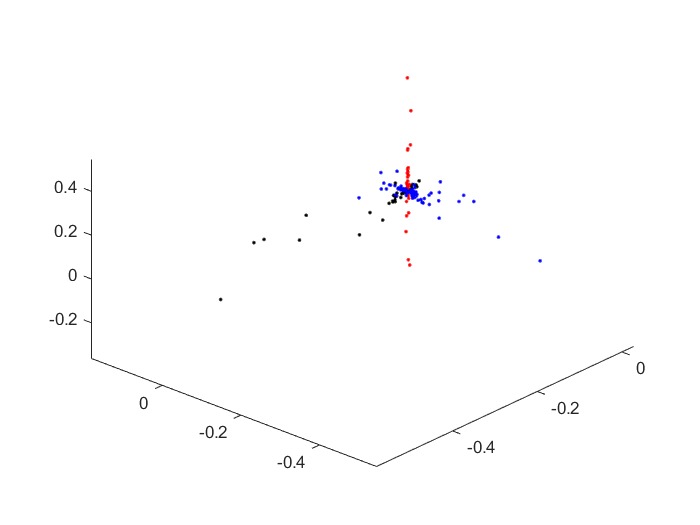

% Graph: 1-3rd PC
plot3(Vst(toy(:, 3) == 1, 1), Vst(toy(:, 3) == 1, 2), Vst(toy(:, 3) == 1, 3), 'b.', ...
    Vst(toy(:, 3) == 2, 1), Vst(toy(:, 3) == 2, 2), Vst(toy(:, 3) == 2, 3), 'k.', ...
    Vst(toy(:, 3) == 3, 1), Vst(toy(:, 3) == 3, 2), Vst(toy(:, 3) == 3, 3), 'r.')

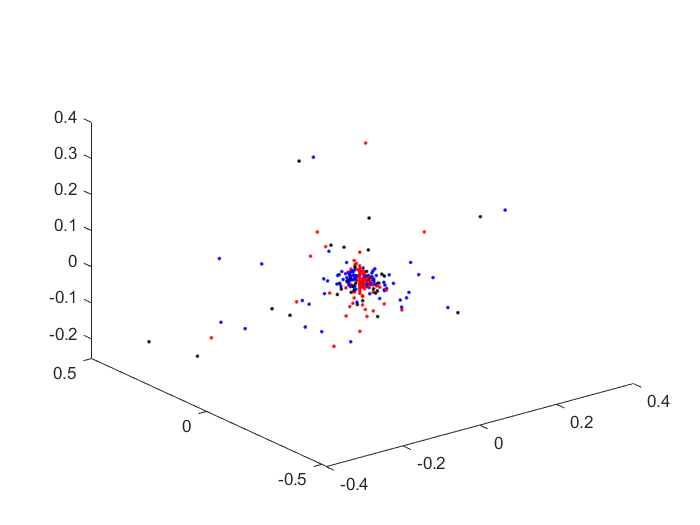


% Graph: 4-6th PC
plot3(Vst(toy(:, 3) == 1, 4), Vst(toy(:, 3) == 1, 5), Vst(toy(:, 3) == 1, 6), 'b.', ...
    Vst(toy(:, 3) == 2, 4), Vst(toy(:, 3) == 1, 5), Vst(toy(:, 3) == 1, 6), 'k.', ...
    Vst(toy(:, 3) == 3, 4), Vst(toy(:, 3) == 1, 5), Vst(toy(:, 3) == 1, 6), 'r.')